## fv0 Intro

This scrip import expomential fitness as experiment data, and simulation result comes from GLE model with no inertia term.

## Import data and previewing

The data come from expomential fitness data.

experiment_interval=5;
min_length=51;
time_scale=experiment_interval*(1:min_length);

fun=inline('a(1)*exp(a(2)*t)+a(3)*exp(a(4)*t)','a','t');
t=time_scale;
a(1)=1.046e+05;%p47_5s
a(2)=0.0004364;
a(3)=-7.307e+04;
a(4)=-0.03125;

Reserved_length=min_length;
interceptive_experiment_MSD=1e-18*fun(a,time_scale);

## Parameter importing

GLE parameter

kB=1.3806505e-23;
T=293;%confirmed
m=6.0244E-9;
psi=0.2017;
zeta=2.0060E-8;
H=0.7569;

## Main loop

simulation_MSD=[];
tau=((zeta*gamma(2*H+1))/(m*psi))^(1/(2-2*H));
for t=experiment_interval*[1:min_length]
    simulation_MSD=[simulation_MSD,kB*T/(m*psi)*mlf(2-2*H,1,-(t/tau)^(2-2*H),6)];
end

## Plot and saving

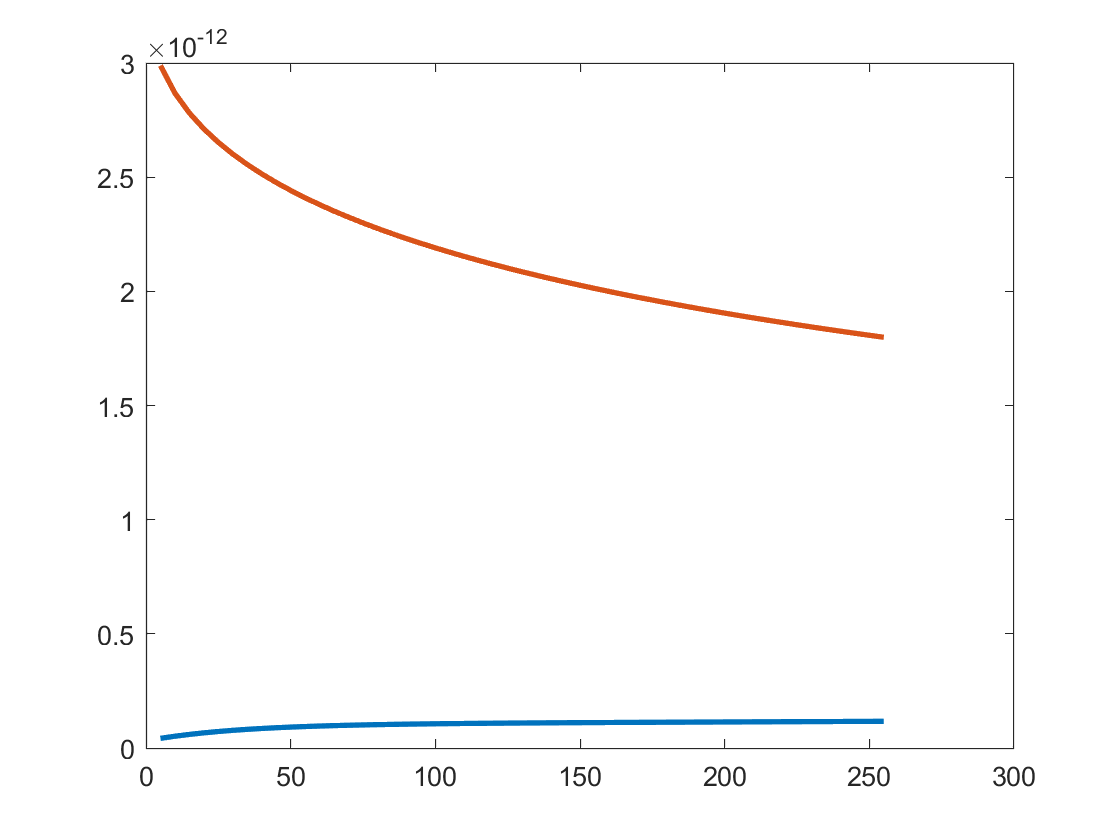

figure
plot(time_scale,interceptive_experiment_MSD,"LineWidth",2)
hold on
plot(time_scale,simulation_MSD,"LineWidth",2)